# EngineFaultDB: Automotive Engine Fault Classification

## Data Preparation

clc; clear; close all;

Data_location = "../Datasets/EngineFaultDB_Final.xlsx";
data = readtable(Data_location, 'VariableNamingRule', 'preserve');
data_fault0 = data(1:16000, :);
data_fault1 = data(16001:26998, :);
data_fault2 = data(26999:41998, :);
data_fault3 = data(41999:end, :);

data.Properties

ans =   TableProperties - 속성 있음:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Fault'  'MAP'  'TPS'  'Force'  'Power'  'RPM'  'Consumption L/H'  'Consumption L/100KM'  'Speed'  'CO'  'HC'  'CO2'  'O2'  'Lambda'  'AFR'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: 사용자 지정 속성을 설정하지 않았습니다.
 addprop 및 rmprop을(를) 사용하여 CustomProperties를 수정하십시오.


% Data Length Configuration
% Fault 0 : 16,000
% Fault 1 : 10,988
% Fault 2 : 15,000
% Fault 3 : 14,001
L0 = height(data_fault0);
L1 = height(data_fault1);
L2 = height(data_fault2);
L3 = height(data_fault3);

ans = 1×15 cell 배열
    {'Fault'}    {'MAP'}    {'TPS'}    {'Force'}    {'Power'}    {'RPM'}    {'Consumption L/H'}    {'Consumption L/100KM'}    {'Speed'}    {'CO'}    {'HC'}    {'CO2'}    {'O2'}    {'Lambda'}    {'AFR'}


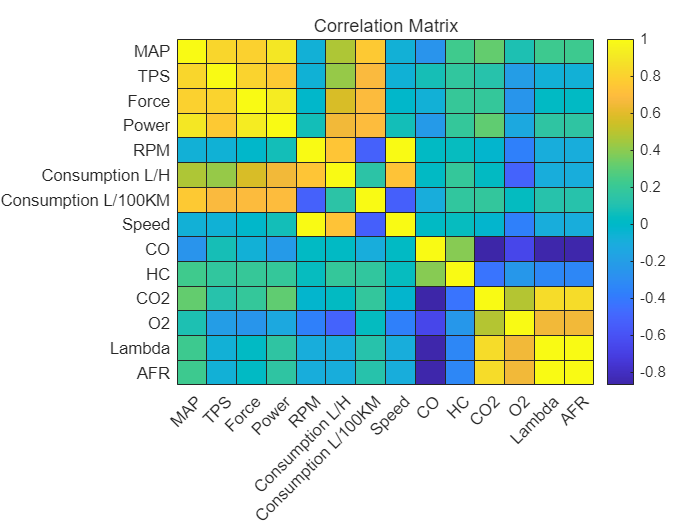

variable_names = data.Properties.VariableNames(2:15);

corr_matrix = corrcoef(table2array(data_fault0(:, 2:15)));
heatmap(corr_matrix, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Correlation Matrix', 'Colormap', parula);

disp(corr_matrix);

    1.0000    0.8246    0.7993    0.9023   -0.0678    0.4745    0.7637   -0.0694   -0.2580    0.2310    0.3204    0.0882    0.2255    0.2255
    0.8246    1.0000    0.8074    0.7658   -0.0598    0.4200    0.6823   -0.0610    0.0763    0.1745    0.1212   -0.2002   -0.0687   -0.0687
    0.7993    0.8074    1.0000    0.9259   -0.0083    0.5723    0.6932   -0.0094   -0.0700    0.1949    0.1842   -0.2502    0.0213    0.0213
    0.9023    0.7658    0.9259    1.0000    0.0689    0.6552    0.6984    0.0676   -0.2256    0.1883    0.3094   -0.1287    0.1547    0.1546
   -0.0678   -0.0598   -0.0083    0.0689    1.0000    0.7385   -0.5244    0.9973    0.0193    0.0382   -0.0284   -0.3710   -0.1002   -0.1002
    0.4745    0.4200    0.5723    0.6552    0.7385    1.0000    0.1423    0.7372    0.0169    0.1832    0.0268   -0.5106   -0.0992   -0.0992
    0.7637    0.6823    0.6932    0.6984   -0.5244    0.1423    1.0000   -0.5263   -0.0955    0.1701    0.1769    0.0325    0.1171    0.1171
   -0.0694   

corr_threshold = 0.8;
selected_variables = array2table(corr_matrix);
selected_variables.Properties.VariableNames = variable_names;
[row, col] = find(corr_matrix > corr_threshold);


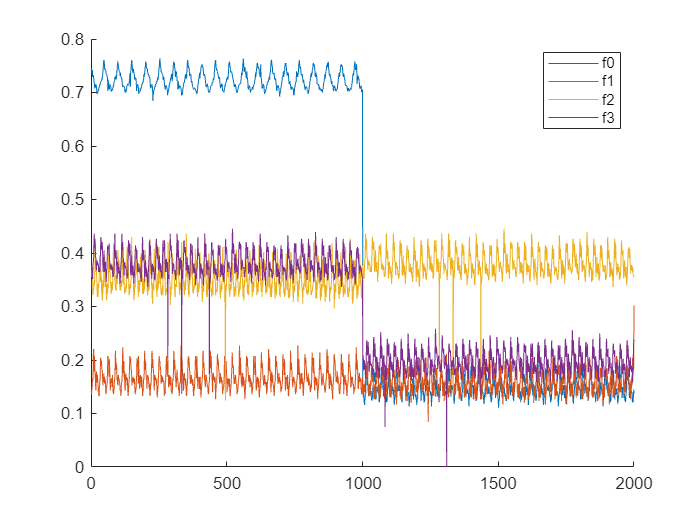

% f0_MAP = rescale(data_fault0.MAP);
% f1_MAP = rescale(data_fault1.MAP);
% f2_MAP = rescale(data_fault2.MAP);
% f3_MAP = rescale(data_fault3.MAP);
% 
% figure;
% hold on;
% plot(1:2000, f0_MAP(1:2000, :));
% plot(1:2000, f1_MAP(1:2000, :));
% plot(1:2000, f2_MAP(1:2000, :));
% plot(1:2000, f3_MAP(1:2000, :));
% legend("f0", "f1", "f2", "f3");

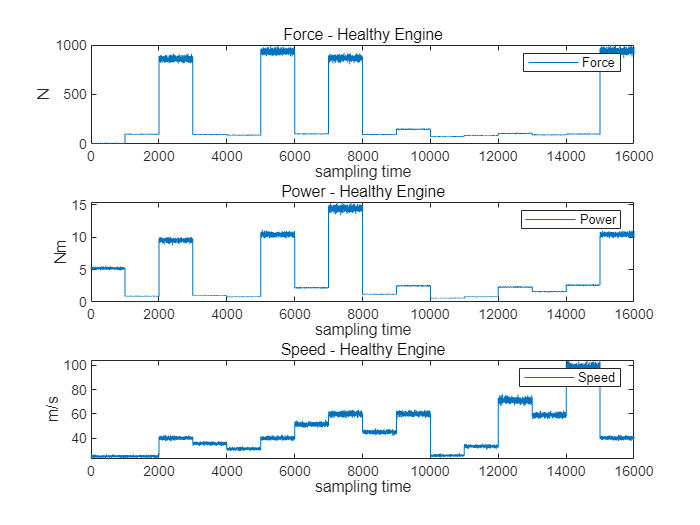

% figure();
% t = 1:16000;
% Force = table2array(data(1:16000, 4));
% Power = table2array(data(1:16000, 5));
% Speed = table2array(data(1:16000, 9));
% 
% hold on;
% subplot(3,1,1);
% plot(t, Force);
% title("Force - Healthy Engine");
% ylabel("N");
% xlabel("sampling time");
% legend("Force")
% 
% subplot(3,1,2);
% plot(t, Power);
% title("Power - Healthy Engine");
% ylabel("Nm");
% xlabel("sampling time");
% legend("Power")
% 
% subplot(3,1,3);
% plot(t, Speed);
% title("Speed - Healthy Engine");
% ylabel("m/s");
% xlabel("sampling time");
% legend("Speed")
% 
% hold off;

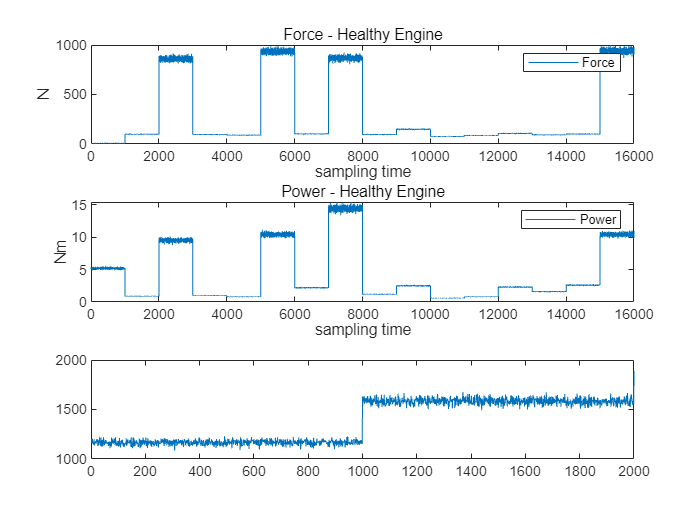

% t_2=1:2000;
% RPM_fault1 = table2array(data(16001:16001+1999, 6));
% plot(t_2,RPM_fault1);